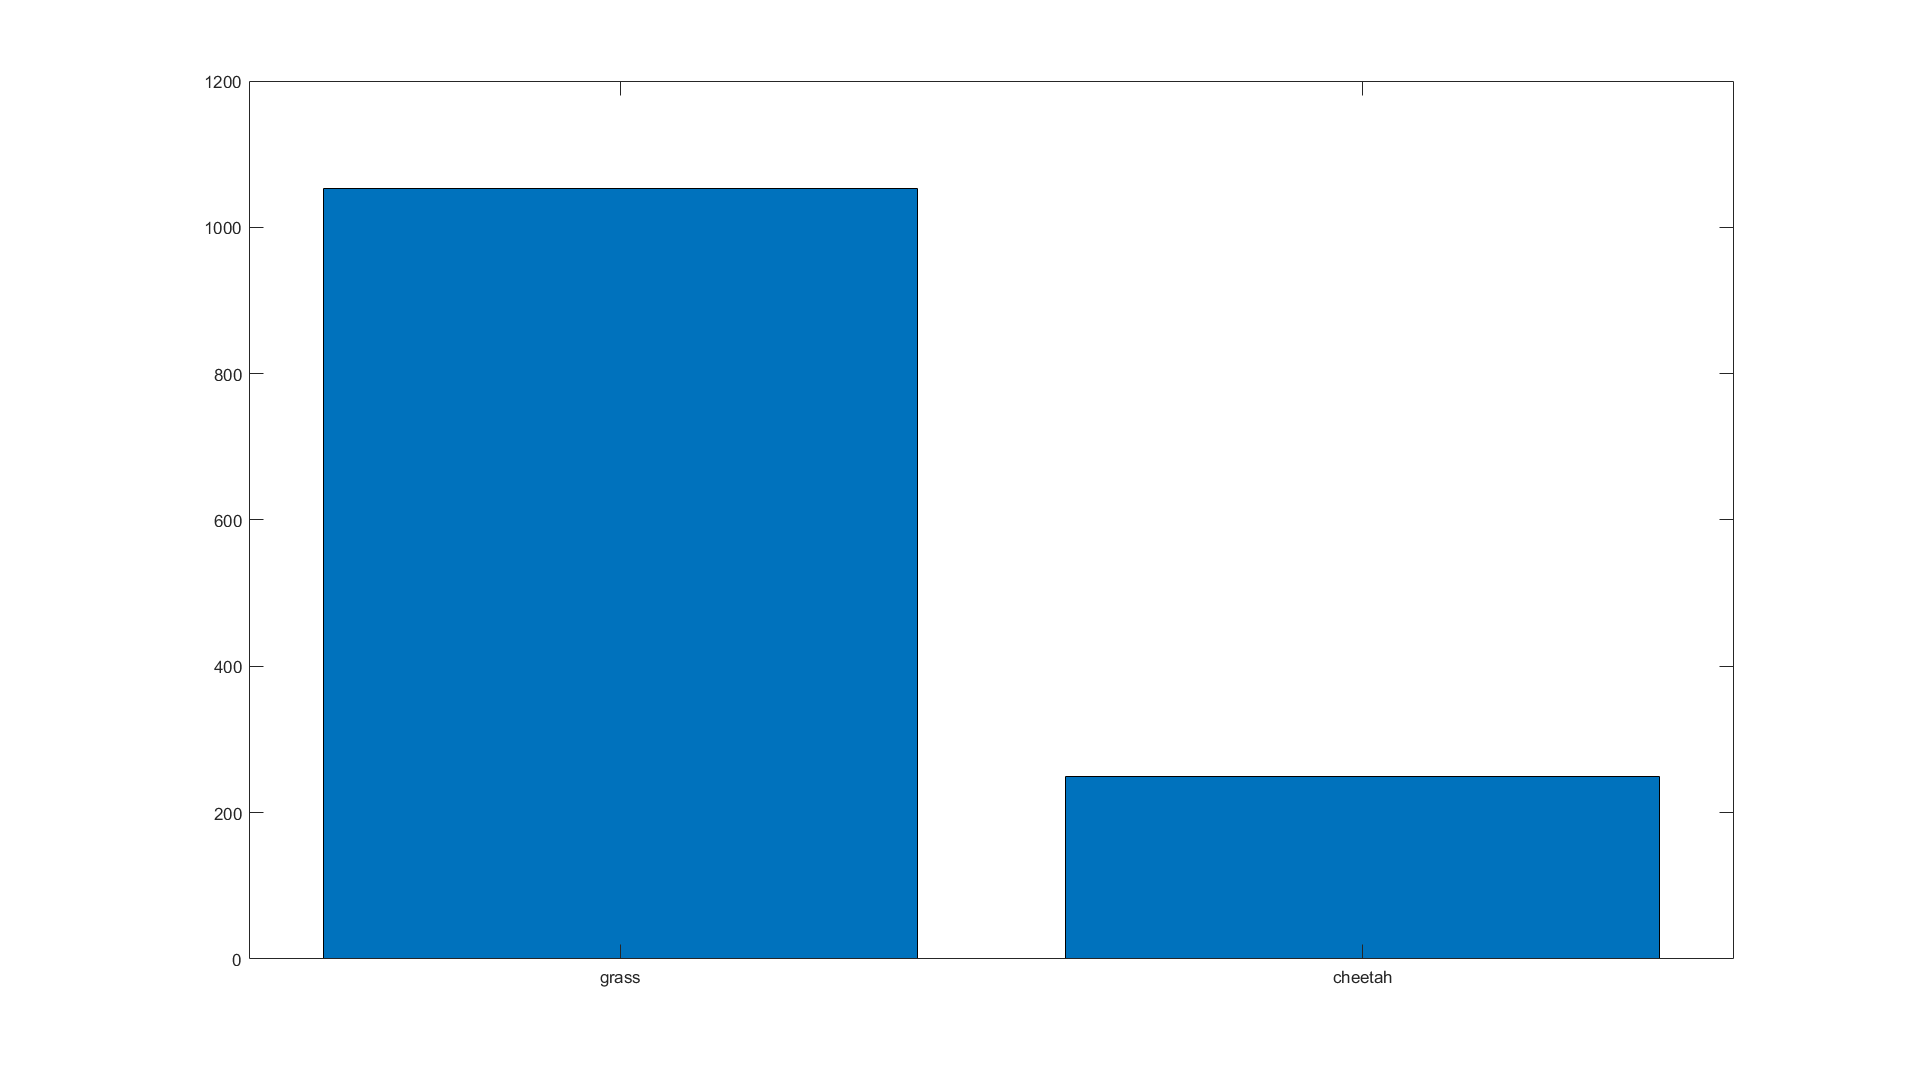

load("HW2\TrainingSamplesDCT_8_new.mat")

% Compute priors using MLE results in Prob 2
c_fg = size(TrainsampleDCT_FG, 1);
c_bg = size(TrainsampleDCT_BG, 1);
n = c_fg + c_bg;
X = categorical({'grass', 'cheetah'});
X = reordercats(X, {'grass', 'cheetah'});
Y = [c_bg c_fg];
bar(X, Y)

prob_bg = c_bg / n

prob_bg = 0.8081

prob_fg = c_fg / n

prob_fg = 0.1919

% MLE for class conditional densities
% BG
mean_bg_est = mean(TrainsampleDCT_BG, 1)

mean_bg_est =     2.9153   -0.0037    0.0066   -0.0007    0.0029   -0.0035    0.0006    0.0002    0.0011    0.0011   -0.0005    0.0001   -0.0012    0.0017   -0.0014    0.0015    0.0007    0.0005    0.0014    0.0009    0.0001   -0.0006   -0.0005   -0.0002   -0.0008   -0.0000    0.0001    0.0003    0.0000   -0.0004   -0.0003   -0.0002   -0.0002   -0.0006    0.0003    0.0004   -0.0000   -0.0004   -0.0003   -0.0001   -0.0004    0.0004    0.0001    0.0002    0.0001   -0.0002   -0.0004    0.0001   -0.0001   -0.0001


var_bg_est = 0;
for i = 1:size(TrainsampleDCT_BG, 1)
    var_bg_est = var_bg_est + (TrainsampleDCT_BG(i, :) - mean_bg_est).'...
        *(TrainsampleDCT_BG(i, :) - mean_bg_est)./size(TrainsampleDCT_BG, 1);
end
var_bg_est

var_bg_est =     0.3195    0.0050   -0.0023   -0.0068    0.0017   -0.0043   -0.0010   -0.0006   -0.0000   -0.0004   -0.0024   -0.0000   -0.0004    0.0004   -0.0008    0.0004   -0.0002    0.0008   -0.0003   -0.0003   -0.0000   -0.0004   -0.0001    0.0002   -0.0002    0.0008    0.0009   -0.0003    0.0001   -0.0002   -0.0001    0.0002    0.0004    0.0003   -0.0001   -0.0001    0.0000    0.0002    0.0000    0.0001   -0.0001   -0.0001    0.0000    0.0000    0.0002    0.0001    0.0001   -0.0000   -0.0000    0.0000
    0.0050    0.0208   -0.0037   -0.0004    0.0002    0.0000   -0.0006    0.0008   -0.0021   -0.0003   -0.0000   -0.0001    0.0001   -0.0001   -0.0000   -0.0002   -0.0002    0.0001    0.0000   -0.0006   -0.0001    0.0000   -0.0000   -0.0000    0.0001    0.0000    0.0001   -0.0001   -0.0001    0.0001   -0.0001   -0.0000    0.0001   -0.0000   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001    0.0001   -0.0000   -0.0000    0.0000   -0.0000    0.0001   -0.0000   -0.0000   -0.

% FG
mean_fg_est = mean(TrainsampleDCT_FG, 1)

mean_fg_est =     1.2814    0.0336   -0.0324    0.0171   -0.0035    0.0025   -0.0007    0.0106    0.0022   -0.0021   -0.0030   -0.0005    0.0023    0.0004   -0.0001   -0.0012    0.0042   -0.0022    0.0010    0.0001   -0.0010    0.0005   -0.0016    0.0003    0.0028    0.0040    0.0037   -0.0006    0.0023    0.0020   -0.0021   -0.0021    0.0029    0.0004    0.0005   -0.0008   -0.0001    0.0004   -0.0023   -0.0006    0.0011   -0.0007   -0.0009    0.0013   -0.0020   -0.0008    0.0015   -0.0000    0.0001   -0.0010


var_fg_est = 0;
for i = 1:size(TrainsampleDCT_FG, 1)
    var_fg_est = var_fg_est + (TrainsampleDCT_FG(i, :) - mean_fg_est).'...
        *(TrainsampleDCT_FG(i, :) - mean_fg_est)./size(TrainsampleDCT_FG, 1);
end
var_fg_est

var_fg_est =     0.1908    0.0266   -0.0258   -0.0009    0.0062   -0.0038    0.0029    0.0050   -0.0060    0.0025   -0.0012    0.0014   -0.0019   -0.0003   -0.0011    0.0022   -0.0001    0.0006   -0.0028   -0.0005    0.0003    0.0003   -0.0005    0.0007   -0.0000    0.0015    0.0001   -0.0009   -0.0003   -0.0001   -0.0016    0.0006    0.0009   -0.0003   -0.0006    0.0004    0.0001   -0.0004    0.0002   -0.0007    0.0003   -0.0009   -0.0003    0.0001    0.0008   -0.0005   -0.0002    0.0001   -0.0000   -0.0000
    0.0266    0.0472   -0.0104   -0.0019    0.0010   -0.0010   -0.0019    0.0030   -0.0054   -0.0005   -0.0005    0.0005    0.0009   -0.0008    0.0006   -0.0004   -0.0008    0.0013   -0.0005   -0.0008    0.0000   -0.0001   -0.0002    0.0006   -0.0001    0.0008   -0.0006   -0.0005   -0.0004    0.0003   -0.0002    0.0008   -0.0002   -0.0001   -0.0007   -0.0002   -0.0001   -0.0001    0.0001   -0.0004   -0.0003   -0.0001   -0.0001    0.0002   -0.0000   -0.0001   -0.0000    0.0002   -0.

% Plot marginal densities for all features
for j = 1:8
    figure(j);
    set(gcf,'outerposition',get(0,'screensize'));
    tiledlayout(2,4)
    for i = (j-1)*8+1:j*8
        nexttile
        x_low_bg = mean_bg_est(1, i) - 2 * sqrt(var_bg_est(i, i)); 
        x_low_fg = mean_fg_est(1, i) - 2 * sqrt(var_fg_est(i, i));
        x_up_bg = mean_bg_est(1, i) + 2 * sqrt(var_bg_est(i, i));
        x_up_fg = mean_fg_est(1, i) + 2 * sqrt(var_fg_est(i, i));
        p_bg = normpdf(x_low_bg:1e-6:x_up_bg, mean_bg_est(1, i), var_bg_est(i, i));
        p_fg = normpdf(x_low_fg:1e-6:x_up_fg, mean_fg_est(1, i), var_fg_est(i, i));
        plot(x_low_bg:1e-6:x_up_bg, p_bg, 'r');
        hold on
        plot(x_low_fg:1e-6:x_up_fg, p_fg, 'b');
        xlabel(append('Feature ', int2str(i)))
        ylabel('Marginal Density')
        legend('grass','cheetah')
    end
end

% best 8 features
best_8_indices = [1 33 34 39 45 47 50 57];
% [1 33 34 39 45 47 50 57] 0.0501
figure(9)
set(gcf,'outerposition',get(0,'screensize'));
tiledlayout(2,4)
for i = 1:size(best_8_indices, 2)
    nexttile
    x_low_bg = mean_bg_est(1, best_8_indices(1, i)) - 2 * sqrt(var_bg_est(best_8_indices(1, i), best_8_indices(1, i))); 
    x_low_fg = mean_fg_est(1, best_8_indices(1, i)) - 2 * sqrt(var_fg_est(best_8_indices(1, i), best_8_indices(1, i)));
    x_up_bg = mean_bg_est(1, best_8_indices(1, i)) + 2 * sqrt(var_bg_est(best_8_indices(1, i), best_8_indices(1, i)));
    x_up_fg = mean_fg_est(1, best_8_indices(1, i)) + 2 * sqrt(var_fg_est(best_8_indices(1, i), best_8_indices(1, i)));
    p_bg = normpdf(x_low_bg:1e-6:x_up_bg, mean_bg_est(1, best_8_indices(1, i)), var_bg_est(best_8_indices(1, i), best_8_indices(1, i)));
    p_fg = normpdf(x_low_fg:1e-6:x_up_fg, mean_fg_est(1, best_8_indices(1, i)), var_fg_est(best_8_indices(1, i), best_8_indices(1, i)));
    plot(x_low_bg:1e-6:x_up_bg, p_bg, 'r');
    hold on
    plot(x_low_fg:1e-6:x_up_fg, p_fg, 'b');
    xlabel(append('Feature ', int2str(best_8_indices(1, i))))
    ylabel('Marginal Density')
    legend('grass','cheetah')
end
sgtitle('Best 8 Features')

% worst 8 features
worst_8_indices = [2 3 4 5 6 8 37 63];
figure(10)
set(gcf,'outerposition',get(0,'screensize'));
tiledlayout(2,4)
for i = 1:size(worst_8_indices, 2)
    nexttile
    x_low_bg = mean_bg_est(1, worst_8_indices(1, i)) - 2 * sqrt(var_bg_est(worst_8_indices(1, i), worst_8_indices(1, i))); 
    x_low_fg = mean_fg_est(1, worst_8_indices(1, i)) - 2 * sqrt(var_fg_est(worst_8_indices(1, i), worst_8_indices(1, i)));
    x_up_bg = mean_bg_est(1, worst_8_indices(1, i)) + 2 * sqrt(var_bg_est(worst_8_indices(1, i), worst_8_indices(1, i)));
    x_up_fg = mean_fg_est(1, worst_8_indices(1, i)) + 2 * sqrt(var_fg_est(worst_8_indices(1, i), worst_8_indices(1, i)));
    p_bg = normpdf(x_low_bg:1e-6:x_up_bg, mean_bg_est(1, worst_8_indices(1, i)), var_bg_est(worst_8_indices(1, i), worst_8_indices(1, i)));
    p_fg = normpdf(x_low_fg:1e-6:x_up_fg, mean_fg_est(1, worst_8_indices(1, i)), var_fg_est(worst_8_indices(1, i), worst_8_indices(1, i)));
    plot(x_low_bg:1e-6:x_up_bg, p_bg, 'r');
    hold on
    plot(x_low_fg:1e-6:x_up_fg, p_fg, 'b');
    xlabel(append('Feature ', int2str(worst_8_indices(1, i))))
    ylabel('Marginal Density')
    legend('grass','cheetah')
end
sgtitle('Worst 8 Features')

ZigZagPattern = readmatrix('HW1\Zig-Zag Pattern.txt');
ZigZagPattern = ZigZagPattern + 1;
ZigZagPattern = int8(ZigZagPattern);

img = imread("HW1\cheetah.bmp");
img = im2double(img);

% Zero Padding
% right = zeros(255, 7);
% bottom = zeros(7, 277);
% img_pad = [[img right]; bottom];
left = zeros(255, 3);
right = zeros(255, 4);
up = zeros(3, 277);
bottom = zeros(4, 277);
img_pad = [up; [left img right]; bottom];

% DCT
img_dct = dct_8(img, img_pad);

% ZigZag Scan
img_scan = blockproc(img_dct, [8 8], @(block_struct) ZigZagScan(block_struct.data, ZigZagPattern));

% BDR 64D Gaussian
mask_64 = blockproc(img_scan, [1, 64], @(block_struct) BDR(block_struct.data, mean_bg_est, mean_fg_est, var_bg_est, var_fg_est, prob_bg, prob_fg));
mask_64 = int8(mask_64)

mask_64 = 255×270 int8 matrix
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

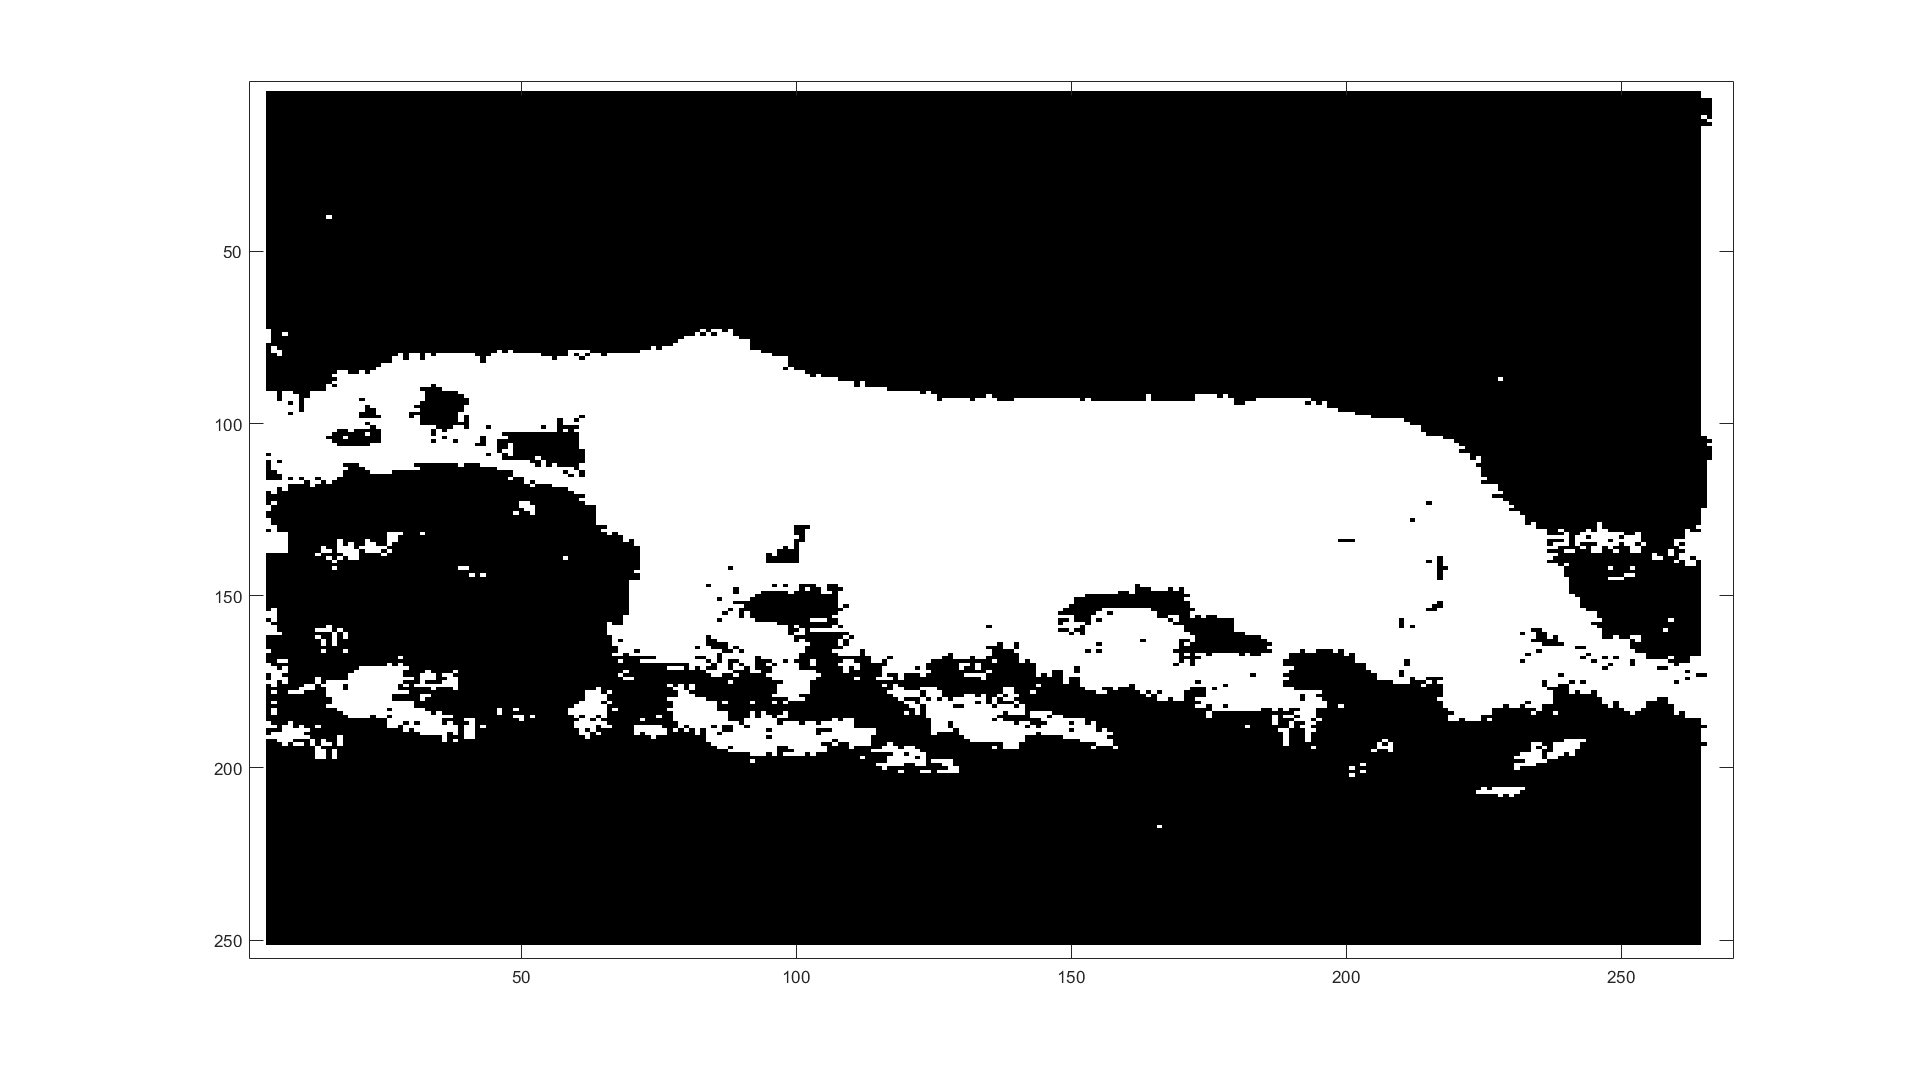

imagesc(mask_64)
colormap(gray(255))

% BDR 8D Gaussian
mean_bg_est_8 = best_8_v(mean_bg_est, best_8_indices);
mean_fg_est_8 = best_8_v(mean_fg_est, best_8_indices);
var_bg_est_8 = best_8_m(var_bg_est, best_8_indices);
var_fg_est_8 = best_8_m(var_fg_est, best_8_indices);
img_scan_8 = blockproc(img_scan, [1 64], @(block_struct) best_8_v(block_struct.data, best_8_indices));
mask_8 = blockproc(img_scan_8, [1, 8], @(block_struct) BDR(block_struct.data, mean_bg_est_8, mean_fg_est_8, var_bg_est_8, var_fg_est_8, prob_bg, prob_fg));
mask_8 = int8(mask_8);

ground_truth = imread("HW1\cheetah_mask.bmp");
ground_truth = im2double(ground_truth);
close all
imagesc(mask_64)
colormap(gray(255))
imagesc(mask_8)
colormap(gray(255))
imagesc(ground_truth)
colormap(gray(255))
ground_truth = int8(ground_truth);

diff_64 = ground_truth - mask_64;
diff_8 = ground_truth - mask_8;
detect_64 = 1 - sum(sum(diff_64==1))/sum(sum(ground_truth==1))
detect_8 = 1 - sum(sum(diff_8==1))/sum(sum(ground_truth==1))
Falarm_64 = sum(sum(diff_64==-1))/sum(sum(ground_truth==0))
Falarm_8 = sum(sum(diff_8==-1))/sum(sum(ground_truth==0))
p_error_64 = Falarm_64 * prob_bg + (1 - detect_64) * prob_fg
p_error_8 = Falarm_8 * prob_bg + (1 - detect_8) * prob_fg

function vector = ZigZagScan(matrix, pattern)
    vector = zeros(1, size(matrix, 1) * size(matrix, 2));
    for i = 1:size(matrix, 1)
        for j = 1:size(matrix, 2)
            position = pattern(i, j);
            vector(1, position) = matrix(i, j);
        end
    end
end

function mask = BDR(feature, mu_bg, mu_fg, sigma_bg, sigma_fg, P_bg, P_fg)
    if (feature-mu_bg)*inv(sigma_bg)*(feature-mu_bg).'+log((2*pi).^64*det(sigma_bg))-2*log(P_bg)...
            < (feature-mu_fg)*inv(sigma_fg)*(feature-mu_fg).'+log((2*pi).^64*det(sigma_fg))-2*log(P_fg)
        mask = 0;
    else
        mask = 1;
    end
end

function dct = dct_8(img, img_pad)
    dct = zeros(size(img, 1) * 8, size(img, 2) * 8);
    for i = 1:size(img, 1)
        for j = 1:size(img, 2)
            dct((8*i-7):(8*i), (8*j-7):(8*j)) = dct2(img_pad(i:i+7, j:j+7));
        end
    end
end

function vector = best_8_v(feat_64, indices)
    vector = feat_64;
    unwanted = setdiff([1:64], indices);
    vector(:, unwanted) = [];
end

function matrix = best_8_m(feat_64, indices)
    matrix = feat_64;
    unwanted = setdiff([1:64], indices);
    matrix(:, unwanted) = [];
    matrix(unwanted, :) = [];
end